# Fugtig luft

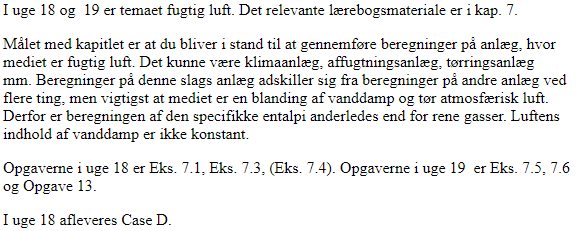

clc; clear;
CP = py.importlib.import_module("CoolProp.CoolProp");

C:\Users\mkeri\anaconda3\lib\site-packages\numpy\__init__.py:143: UserWarning: mkl-service package failed to import, therefore Intel(R) MKL initialization ensuring its correct out-of-the box operation under condition when Gnu OpenMP had already been loaded by Python process is not assured. Please install mkl-service package, see http://github.com/IntelPython/mkl-service
  from . import _distributor_init


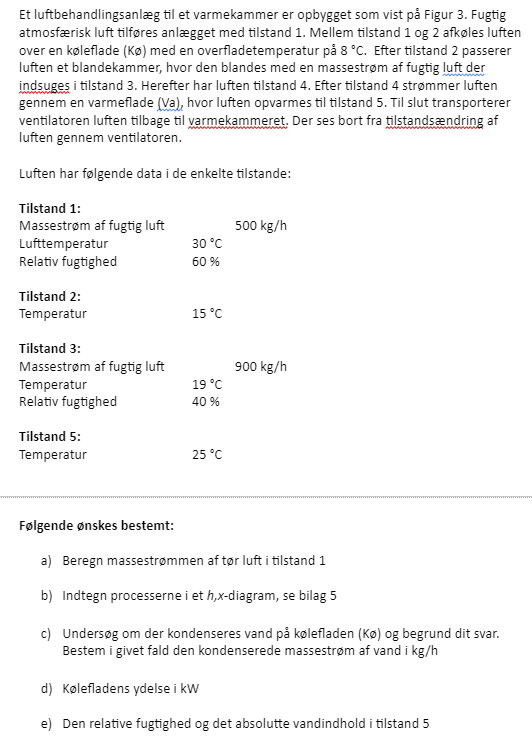

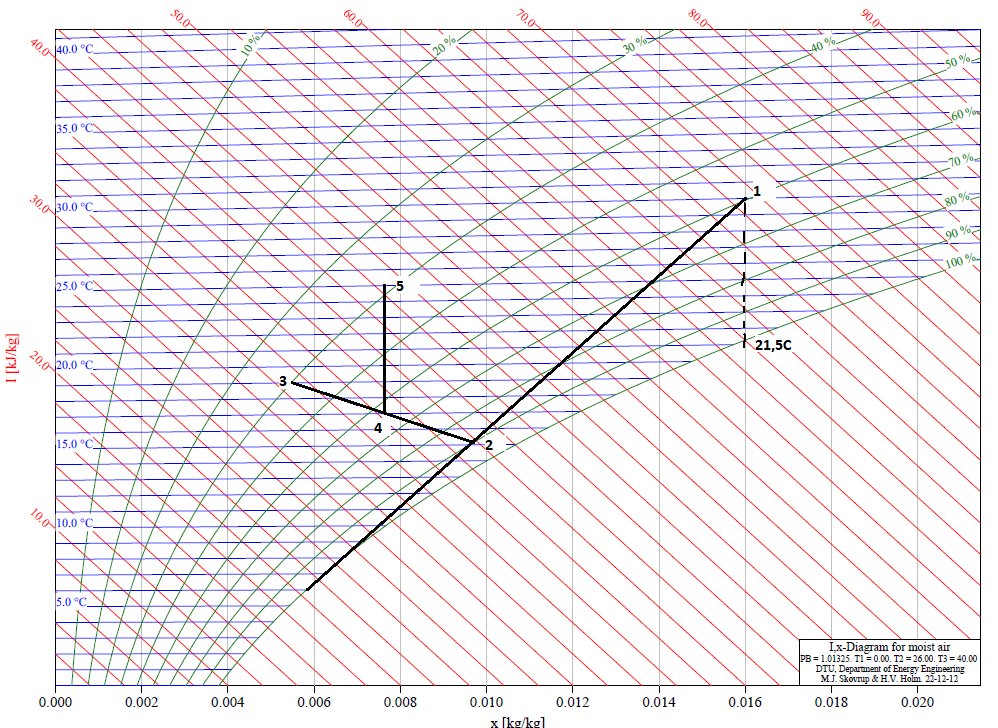

% Opgave a)

qmf = 500; % massestrøm af luft kg/hr
x_fugt = 0.016; % absolutte vandindhold

qmL = qmf * 1/(1+x_fugt) % kg/hr

qmL = 492.1260


% Opgave b - se billede

Betingelsen for udfældning af vand på kølefladen (Kø), er, at overfadetemperaturen her er mindre end dugtemperaturen, som aflæses lodret under punkt 1 og bestemmes til 21,5C. Da overfadetemperaturen på Kø er 8C, er betingelsen tilfredsstillet. En massebalance giver:


$$q_{mv} = q_{mL}(x_2 - x_1)$$


x1 = 0.016

x1 = 0.0160

x2 = 0.01 % fra opgaven, jeg ville nok vælge 0.009

x2 = 0.0100

qmv = qmL * (x1 - x2)

qmv = 2.9528

Der aflæses på diagrammet


$$\Phi_k = q_{mL}(h1 - h2)$$


h1 = 71.6;
h2 = 39.6;
hr = 3600; % alle andre er opgivet i timer, jeg omdanner til sekunder

phi_K = qmL*(h1 - h2)/hr % svaret er i kW eftersom entalpierne er i kJ/kg

phi_K = 4.3745

phi_12 = opvarmningafluft(qmL, h1*1e3, h2*1e3, "nedkol");

Ved opvarmning benyttes energibalancen fra formel 7.39 


$$\Phi_{12}=q_{\mathrm{mL}}\,\left(h_{1}-h_{2}\right)$$

---------------------------------------------------------
Varmestrømmen er fundet til 4.3745 kW
---------------------------------------------------------
        Navn         Størrelse     Enhed 
    _____________    _________    _______

    "Varmestrøm"      4374.5      "W"    
    "Entalpi 1"        71600      "J/kg" 
    "Entalpi 2"        39600      "J/kg" 
    "Tør luft qm"     492.13      "kg/hr"



Værdierne aflæses i h-x digrammet

x = 0.007 kg/kg

phi = 37%

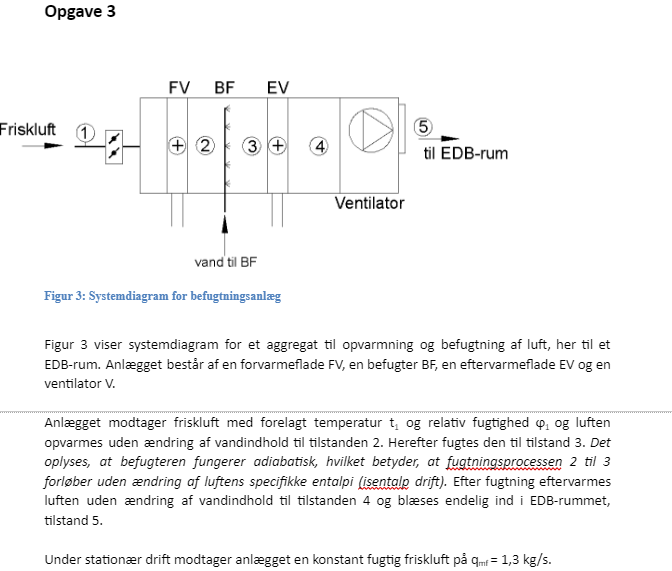

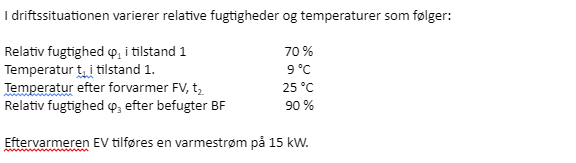

hr = 3600;

x_fugt = 0.0053;
qmf = 1.3*hr

qmf = 4680


qmL = qmf * 1/(1+x_fugt)

qmL = 4.6553e+03


$$q_{mL} = q_{mf} \cdot \frac{1}{1+x} = 4.655 \cdot 10^3 \,\mathrm\frac{kg}{hr}$$


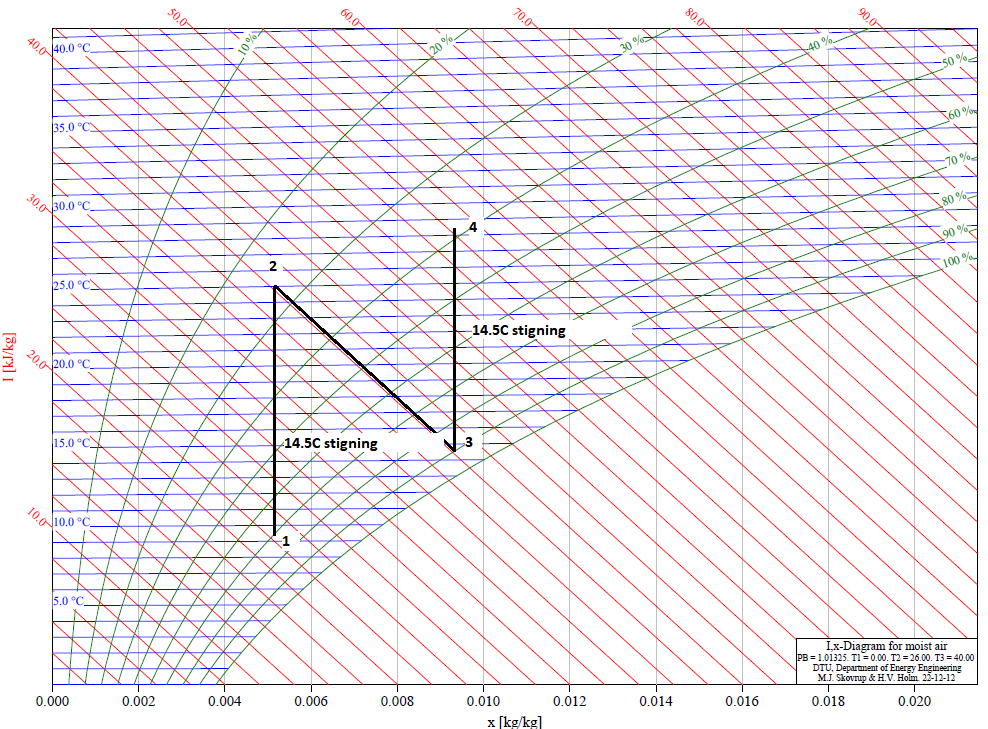

kun 14C stigning

pkt1 = [9, 21.7, 0.0053, 70];
pkt2 = [25, 38.3, 0.0053, 27.5];
pkt3 = [9, 38.3, 0.0093, 90];

% til tabel
pkts = ["Punkt 1","Punkt 2", "Punkt 3"];
names = ["Punkter","T | x | h | psi (%)"];

disp(table(pkts',[pkt1;pkt2;pkt3], VariableNames=names))

     Punkter           T | x | h | psi (%)       
    _________    ________________________________

    "Punkt 1"     9      21.7    0.0053        70
    "Punkt 2"    25      38.3    0.0053      27.5
    "Punkt 3"     9      38.3    0.0093        90




$$\Phi_{FV} = q_{mL}(h1 - h2)$$


h1 = 21.7;
h2 = 38.3;
phi_FV = qmL*(h2 - h1)/hr

phi_FV = 21.4662


$$q_{mv} = q_{mL}(x_3 - x_2)$$



x2 = 0.0053

x2 = 0.0053

x3 = 0.0093 % fra opgaven, jeg ville nok vælge 0.009

x3 = 0.0093

qmv = qmL * (x3 - x2)

qmv = 18.6213

Bare aflæs på grafen

# Til funktioner

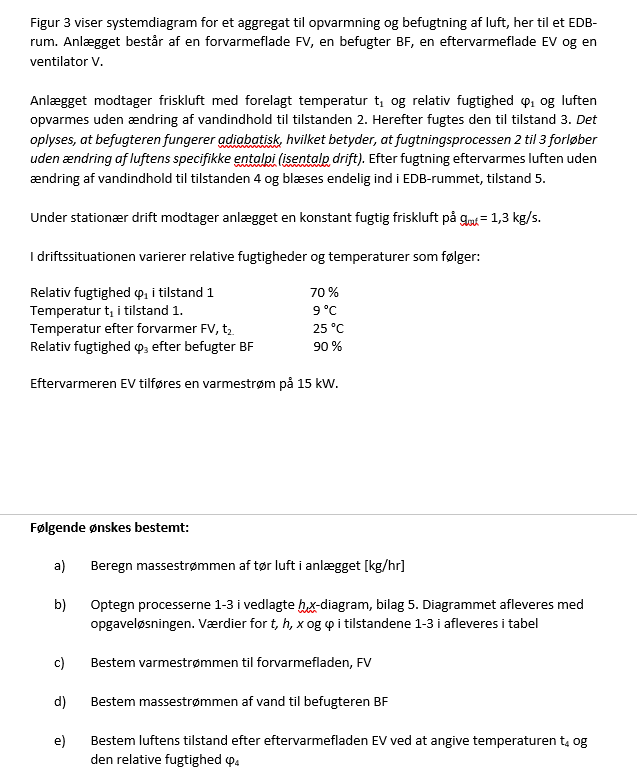

% Opgave a)

% Tilstand 1
T = 9;
phi = 0.70; % i procent
qm_luft = 1.3 * 3600; % kg/hr


x_fugt = CP.HAPropsSI("W","R",phi,"T",273.15+T,"P",101325) % Fugtighedsratio kg/kg

x_fugt = 0.0050



qmL = DryAirMassflow(qm_luft, x_fugt,"kg/hr");

Formel 7.29 bruges til at finde massestrømmen af tør luft


$${\mathrm{qm}}_{\mathrm{dry}}={\mathrm{qm}}_{\mathrm{air}}\,\frac{1}{1+x}$$

---------------------------------------------------------
Massestrømmen af tør luft er fundet til 4656.7461 kg/hr




% Opgave c)

x1 = x_fugt;
x2 = x1;

T1 = 9;
T2 = 25;

% Entalpierne er fundet ved brug af CoolProp

h1 = CP.HAPropsSI("H","W", x1,"T",273.15+T1,"P",101325) % Fugtighedsratio kg/kg

h1 = 2.1619e+04

h2 = CP.HAPropsSI("H","W", x2,"T",273.15+T2,"P",101325) % Fugtighedsratio kg/kg

h2 = 3.7866e+04


phi_12 = opvarmningafluft(qmL, h1, h2, "opvarm");

Ved opvarmning benyttes energibalancen fra formel 7.39


$$\Phi_{12}=q_{\mathrm{mL}}\,\left(h_{2}-h_{1}\right)$$

---------------------------------------------------------
Varmestrømmen er fundet til 21.0159 kW
---------------------------------------------------------
        Navn         Størrelse     Enhed 
    _____________    _________    _______

    "Varmestrøm"       21016      "W"    
    "Entalpi 1"        21619      "J/kg" 
    "Entalpi 2"        37866      "J/kg" 
    "Tør luft qm"     4656.7      "kg/hr"






% Opgave d) bestem massestrømmen af vand til befugteren
phi3 = 0.9;

x2 = 0.0053

x2 = 0.0053

h3 = h2;
x3 = CP.HAPropsSI("W","R",phi3,"H",h3,"P",101325) % Fugtighedsratio kg/kg

x3 = 0.0092


UdskiltVandstrom(qmL, x3, x2,"kg/hr")

Formel 7.41 bruges til at finde den udskilte vandstrøm


$$q_{\mathrm{mv}}=q_{\mathrm{mL}}\,\left(x_{1}-x_{2}\right)$$

---------------------------------------------------------
Den udskilte vandstrøm er fundet til 18.3844 kg/hr


ans = 18.3844

function dryairflow = DryAirMassflow(qm_luft, x_fugt, unit)
%CP = py.importlib.import_module("CoolProp.CoolProp");

% hvor qmluft er den totale massestrøm af luft
% x er fugtighedsratioen 8 kg/kg. Enten fra CP eller plot
% unit er den enhed massestrømmen af luft er givet i (string eks kg/s whatever)

disp("Formel 7.29 bruges til at finde massestrømmen af tør luft")
displayFormula("qm_dry = qm_air * (1/(1+x))")
disp("---------------------------------------------------------")


dryairflow = qm_luft * 1/(1+x_fugt);

disp("")
disp("Massestrømmen af tør luft er fundet til " + dryairflow + " " + unit)

%CP.HAPropsSI("W","R",0.6,"T",273.15+30,"P",101325)

end


function luft_opvarm_nedkol = opvarmningafluft(qml, h1, h2, type)

if type == "opvarm"
    disp("Ved opvarmning benyttes energibalancen fra formel 7.39")
    displayFormula("Phi_12 = q_mL * (h_2 - h_1)")
    disp("---------------------------------------------------------")

    luft_opvarm_nedkol = qml * (h2 - h1)/3600;




elseif type == "nedkol"


    disp("Ved opvarmning benyttes energibalancen fra formel 7.39 ")
    displayFormula("Phi_12 = q_mL * (h_1 - h_2)")
    disp("---------------------------------------------------------")

    luft_opvarm_nedkol = qml * (h1 - h2)/3600;

end

if luft_opvarm_nedkol > 1000
    disp("Varmestrømmen er fundet til " + luft_opvarm_nedkol/1000 + " kW")
else
    disp("Varmestrømmen er fundet til " + luft_opvarm_nedkol + " W")
end

disp("---------------------------------------------------------")


vars = [luft_opvarm_nedkol;h1;h2;qml];
names = ["Varmestrøm";"Entalpi 1";"Entalpi 2";"Tør luft qm"];
units = ["W";"J/kg";"J/kg";"kg/hr"];

disp(table(names,vars,units, VariableNames=["Navn","Størrelse","Enhed"]))




end



function UdV = UdskiltVandstrom(qml, x1, x2, unit)
disp("Formel 7.41 bruges til at finde den udskilte vandstrøm")
displayFormula("q_mv = q_mL * (x_1 - x_2)")
disp("---------------------------------------------------------")


UdV = qml * (x1 - x2);

disp("")
disp("Den udskilte vandstrøm er fundet til " + UdV + " " + unit)



end

